# L1 parameter estimates

t = [3.4935 4.2853 5.1374 5.8181 6.8632 8.1841]';

x = [6 10.1333 14.2667 18.4000 22.5333 26.6667]';

sig = 0.1;
                                                         
m = length(t);

G = [ones(m,1) x]; % matrix G

## No.1

### Use IRLS to find 1-norm estimates for t0 and s2.

tolr = 1e-8;
tolx = 1e-16;
p = 1;
maxiter = 5;

W = (1/sig)*eye(m);
Gw = W*G;
tw = W*t;

ML1 = irls(Gw, tw, tolr, tolx, p, maxiter); % irls function
to = ML1(1)

to = 2.1785

s2 = ML1(2)

s2 = 0.2079

### Plot the data and the fitted model on the same graph

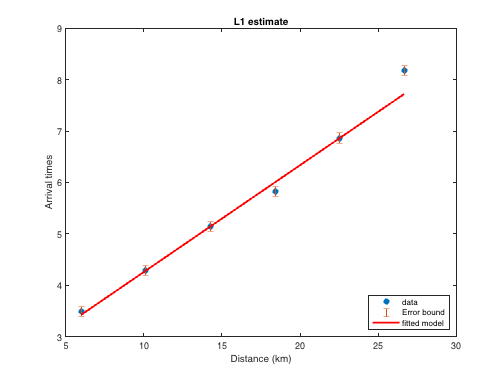

err = sig*ones(size(t));

% fitted model
%T = zeros(m,1);
for i =1:m
    %T(i) = to + s2*x(i);
end
T = to + s2*x(1:m);

%plot
figure1=figure(1);

%L1 estimate
%subplot(2,1,1)
plot(x,t,'.','MarkerSize',20)
hold on
errorbar(x,t,err,'LineStyle','none')
hold on
plot(x,T,'r',LineWidth=2)
hold off
legend('data','Error bound','fitted model','Location','southeast')
ylabel('Arrival times')
xlabel('Distance (km)')
title('L1 estimate')

### Discuss the difference between this figure and the one you created for the least squares estimate in the Well-conditioned

The fitted model in the L1 estimate plot fits the data more than that in the least squares estimate, eventhough the last data point in the L1 estimate curve looks more like an outlier compared to that of the least squares estimate due to its bigger misfit.

## No.2

### Create an ensemble of q data sets

q = 1e4; % no 0f monte carlo simulations
n = 2; % no of parameters

noise = sig*randn(m,q);

db = G*ML1;

M = zeros(q,n);

for i = 1:q
    di = (db + noise(:,i));
    dw = di./sig;
    ML1i = irls(Gw, dw, tolr, tolx, p, maxiter); 
    M(i,1) = ML1i(1); M(i,2) = ML1i(2); 
end

M

M =     2.2668    0.2032
    2.0478    0.2242
    2.2446    0.2060
    2.3429    0.2038
    2.3526    0.1989
    2.0542    0.2103
    2.2263    0.2052
    2.2270    0.2051
    2.3523    0.1972
    2.1596    0.2110


### Create a Q-Q plot for each of the two parameter estimates.

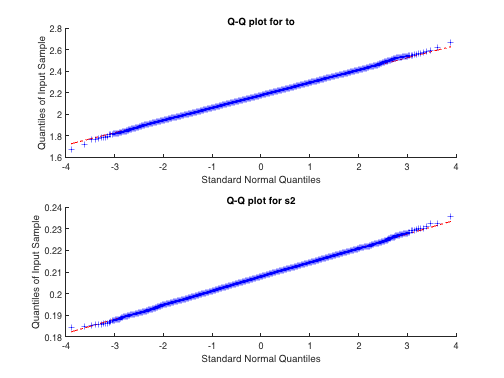

%figure2=figure('Position', [100, 100, 1024, 1200]);
figure(2)
subplot(2,1,1)
qqplot(M(:,1))
ylabel('Quantiles of Input Sample');
xlabel('Standard Normal Quantiles');
title('Q-Q plot for to')
subplot(2,1,2)
qqplot(M(:,2))
ylabel('Quantiles of Input Sample');
xlabel('Standard Normal Quantiles');
title('Q-Q plot for s2')

### Verify that your q is large enough for the Q-Q plot to exhibit a normal distribution

Since  the graphical test from the Q-Q plot depicts that the quantile data and standard normal quantiles almost follow a straight line between -2.5 to 2.5 for parameter, to, and -3 to 3 for parameter, s2, then the selected q is large enough for the Q-Q plot to exhibit a normal distribution.

## No.3

### Estimate the uncertainty in your L1 parameter estimates from 1. using confidence intervals, with two different approaches:

### (a). Find a range where 95% of the ensemble L1 parameter estimates lie, relative to the mean.

mbar = mean(M); % mean
A = M - repmat(mbar,[q],[1]); 
Ai = sort(A);
sigi = Ai(0.95*q,:);

%for to
ct1 = to - sigi(1);
ct2 = to + sigi(1);

Confidence_interval_to = [ct1 ct2]

Confidence_interval_to =     1.9855    2.3716


%for s2
ct11 = s2 - sigi(2);
ct22 = s2 + sigi(2);

Confidence_interval_s2 = [ct11 ct22]

Confidence_interval_s2 =     0.1971    0.2187


### (b). Use the empirical estimate of the covariance given by (2.110).

C = (A'*A)/q; % empirical estimate

%for to
z = 1.96;
ct1 = to - sqrt(C(1,1))*z;%/sqrt(n);
ct2 = to + sqrt(C(1,1))*z;%/sqrt(n);

 Confidence_interval_to = [ct1 ct2]

Confidence_interval_to =     1.9481    2.4090


%for s2
ct11 = s2 - sqrt(C(2,2))*z;%/sqrt(n);
ct22 = s2 + sqrt(C(2,2))*z;%/sqrt(n);

Confidence_interval_s2 = [ct11 ct22]

Confidence_interval_s2 =     0.1949    0.2209


### Discuss how they differ from each other, and how they differ from the least squares confidence intervals.

Using the empirical estimate approach gives a wider confidence interval with a smaller lower bound and a larger upper bound of the interval compared to using the approach in 3(a). Therefore the empirical approach gives us more range of values in which the parameter estimates lie than approach 3(a).  The least squares (lsq) confidence intervals difference between the bounds (upper and lower) lie between the differences between the bounds for each parameter estimate for the two methods. However to from lsq lie between a smaller lower and upper bound of the confidence interval compared to the confidence intervals obtained using both approaches, eventhough s2 obtained using lsq lie between larger lower and upper bounds compared to using both approaches.